# Práctica 2 ~OFDM con Error de Frecuencia

Teresa González y María José Medina

## 2. Definición del sistema OFDM 

Se implementa un sistema de comunicaciones OFDM con portadoras en las frecuencias 40, 60, 80, y 100 KHz, moduladas en QAM. Se asume sin propagación multitrayecto, por lo que no se la ecualización en recepción.

### Definición de los parámetros de transmisión

A continuación se definen los parámetros especificados en los requisitos, se realiza una representación de el espectro de las señales portadoras y se calculan los parámetros necesarios para la correcta transmisión de los símbolos OFDM.

#### Definicion de parámetros especificados en los requisitos

delta_f=20*10^3; % Diferencia entre portadoras
NFFT=32; % Número de muestras de la fft e ifft
Nf=4; % numero de portadoras con datos

#### Representación de las portadoras

La figura siguiente mustra el espectro de las portadoras OFDM. Como se puede observar, se trata de cuatro impulsos en 40, 60, 80 y 100 kHz.

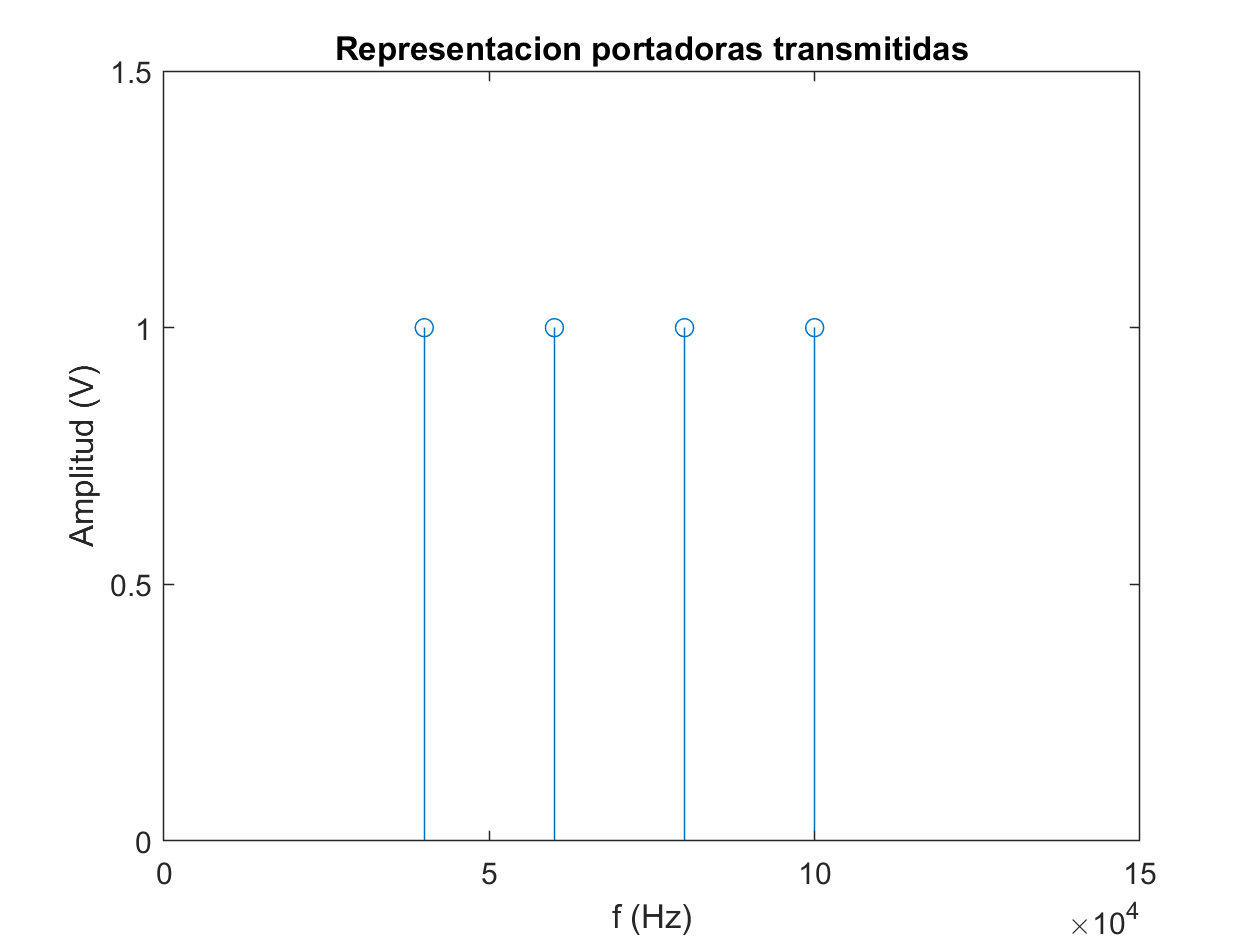

%vector de portadoras
fc= [40,60,80,100]*10^3;

figure
stem(fc,[1,1,1,1])
xlim([0,15*10^4])
ylim([0,1.5])
title("Representacion portadoras transmitidas")
xlabel("f (Hz)")
ylabel("Amplitud (V)")

#### Cálculo de los parámetros

Cálculo de la frecuencia de muestreo y el periodo de IFFT a partir de los parámetros especificados en los requisitos.

Tifft= 1/delta_f; % Periodo de la ifft
Fs= NFFT*delta_f; % Frecuencia de muestreo
Ts=1/Fs; % Periodo de muestreo

### Simulación de la transmisión

Simulacion de la transmisión de una señal binaria mediante OFDM con símbolos modulados en 16-QAM, 64-QAM y 256-QAM. Ya que se asume que no se produce distorsión multicamino, el enlace está compuesto únicamente por los bloques modulador QAM e IFFT en transmisión, y FFT y demodulador en recepción.

Se ha elegido un número de símbolos OFDM de 1600 para obtener valores de BER precisos de hasta $6,25 \cdot{10^{-5}}$.

Nofdm  =  1000;  % Número de símbolos OFDM
m_ary=[16,64,256]; % Niveles N-QAM

% El número de bits debe ser múltiplo de el número de bits por símbolo, el
% número de símbolos OFDM y el número de portadoras.
txbits_16 = round(rand([1,log2(m_ary(1))*Nofdm*Nf]));
txbits_64 = round(rand([1,log2(m_ary(2))*Nofdm*Nf]));
txbits_256 = round(rand([1,log2(m_ary(3))*Nofdm*Nf]));

Después de la creación de la señal a trasmitir se procede a su modulación en N-QAM.

A continuación se representa la constelación 16-QAM. Como se puede observar, se trata de 16 puntos colocados en forma de regilla, con cuatro niveles de fase y cuatro de cuadratura.

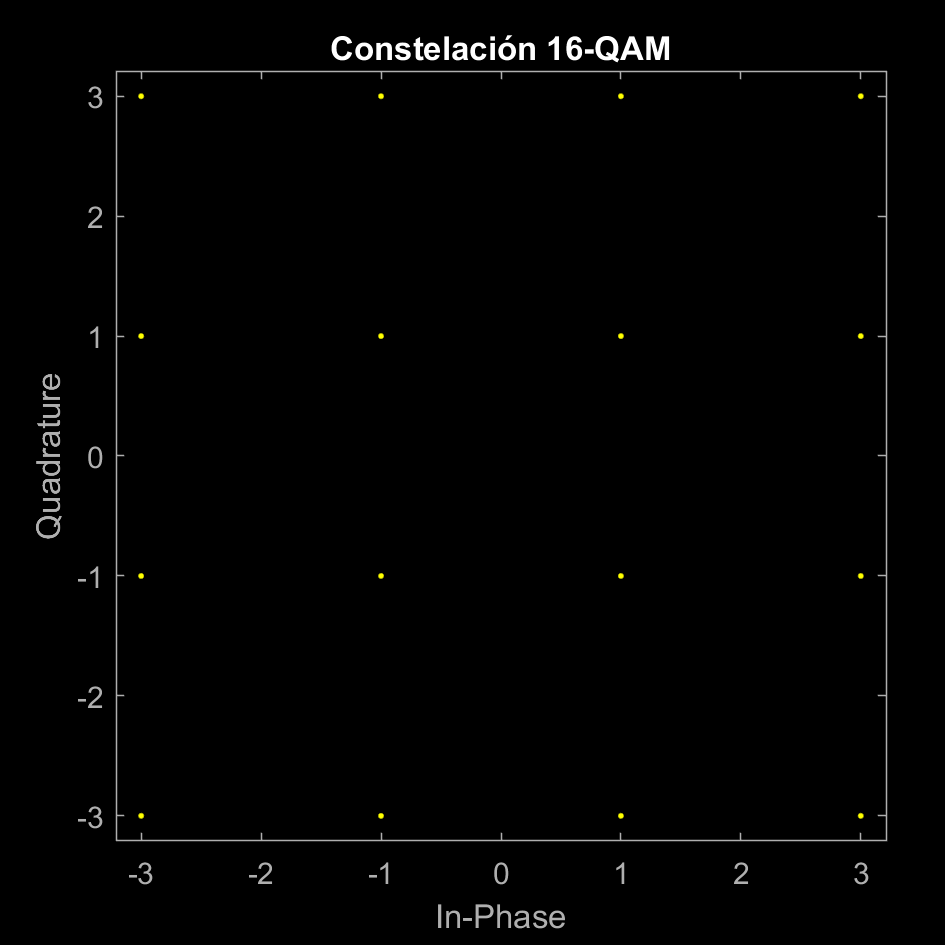

mod_16=qammod(txbits_16',m_ary(1), 'InputType', 'Bit');
scatterplot(mod_16)
title("Constelación 16-QAM")

A continuación se representa la constelación 64-QAM. Esta vez de trata de 64 puntos de nuevo colocados en forma de regilla con ocho niveles de fase y ocho de cuadratura.

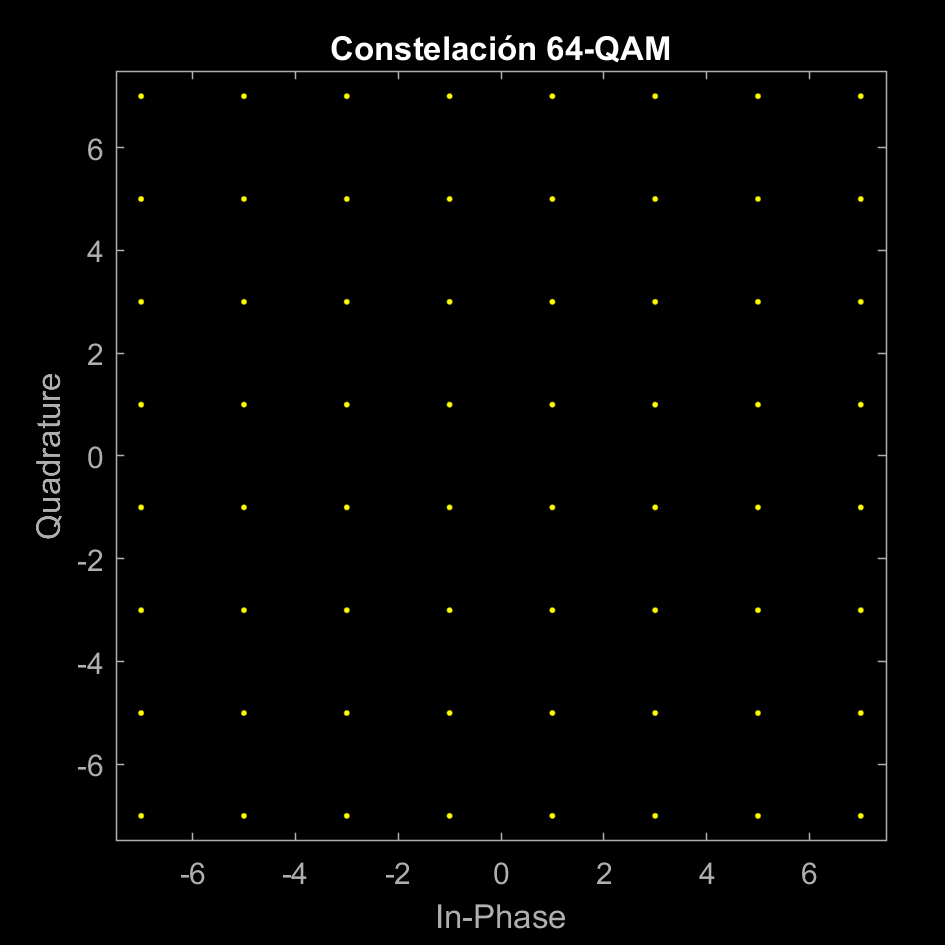

mod_64=qammod(txbits_64',m_ary(2), 'InputType', 'Bit');
scatterplot(mod_64)
title("Constelación 64-QAM")

Por último, se representa la constelación 256-QAM. En esta ocasión cuenta con 256 puntos, 16 niveles de fase y 16 de cuadratura.

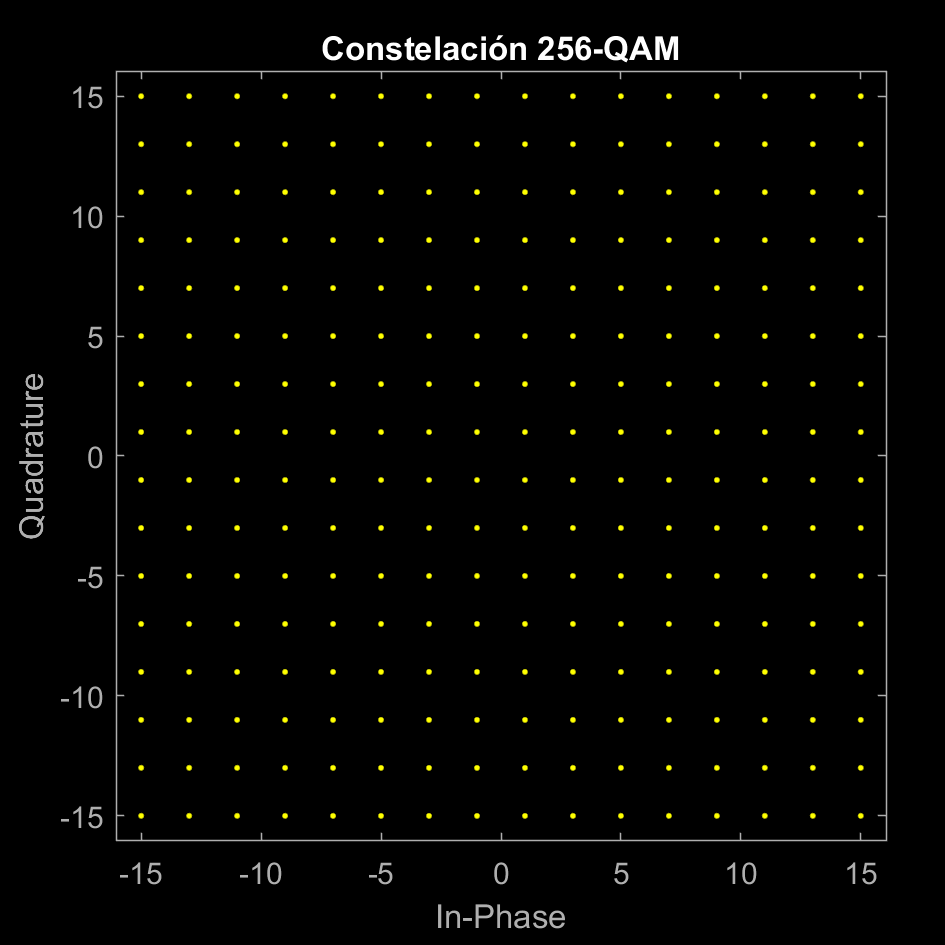

mod_256=qammod(txbits_256',m_ary(3), 'InputType', 'Bit');
scatterplot(mod_256)
title("Constelación 256-QAM")

mod_16= reshape(mod_16, [Nf, Nofdm]);
mod_64= reshape(mod_64, [Nf, Nofdm]);
mod_256= reshape(mod_256, [Nf, Nofdm]);


A continuación se modula la señal en OFDM mediante la transformada inversa de Fourier de una matriz de coeficientes espectrales, la cual se obtiene al recolocar los símbolos complejos a la salida del modulador QPSK. Esta matriz tiene tantas filas como el número de muestras de la FFT y tantas columnas como símbolos OFDM.

%  Incialización a cero
X_16 = zeros(NFFT, Nofdm);
X_64 = zeros(NFFT, Nofdm);
X_256 = zeros(NFFT, Nofdm);

%  Asignación de los símbolos moduladores al espectro positivo
X_16(3:6,:) = mod_16;
X_64(3:6,:) = mod_64;
X_256(3:6,:) = mod_256;

%  Asignación de los símbolos moduladores en orden inverso y conjugados al espectro negativo.
X_16(NFFT/2+2:NFFT,:) = flipud(conj(X_16(2:NFFT/2,:)));
X_64(NFFT/2+2:NFFT,:) = flipud(conj(X_64(2:NFFT/2,:)));
X_256(NFFT/2+2:NFFT,:) = flipud(conj(X_256(2:NFFT/2,:)));

% Generación del vector de muestras temporales reales como resultado de la modulación OFDM.
% Las funcion ifft de Matlab no multiplica por el número de muestras como se debería hacer de forma teórica, por
% lo que se añade manualmente.
x_16= ifft(X_16, NFFT, 'symmetric')*NFFT;
x_64= ifft(X_64, NFFT, 'symmetric')*NFFT;
x_256= ifft(X_256, NFFT, 'symmetric')*NFFT;

% Transformación de x en un vector fila para representar los bits que se transmiten

x_16 = reshape(x_16,  [], 1);
x_64 = reshape(x_64,  [], 1);
x_256 = reshape(x_256,  [], 1);

A continuación se representan la señales temporales (correspondientes a 10 simbolos) moduladas en OFDM sobre 16-QAM, 64-QAM y 256-QAM. 

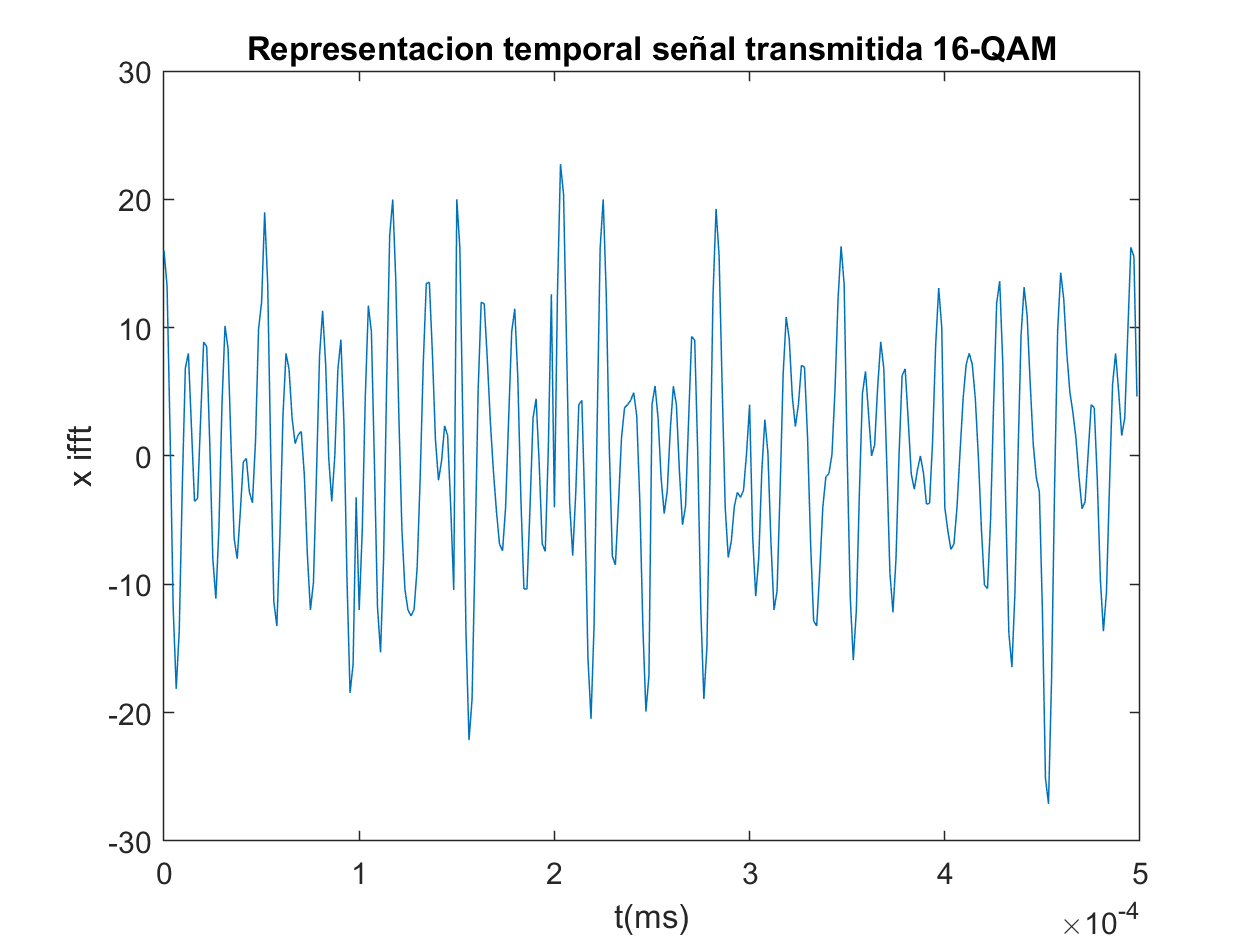

figure;
% Vector temporal correspondientes al periodo de 10 símbolos.
t=0:Ts:10*Tifft-Ts;
plot(t,x_16(1:10*NFFT))
xlabel('t(ms)');
ylabel('x ifft');
title('Representacion temporal señal transmitida 16-QAM');

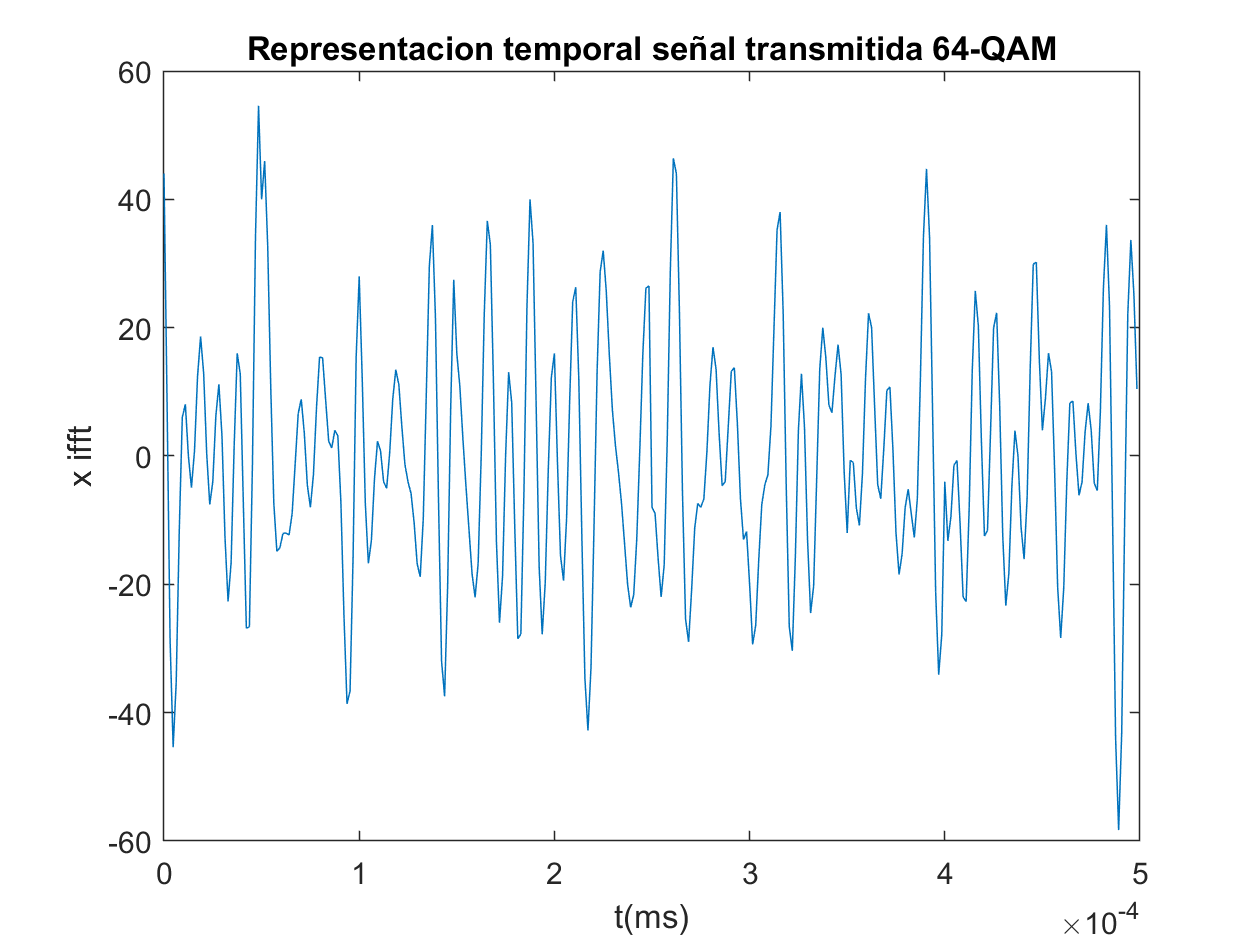

figure;
plot(t,x_64(1:10*NFFT))
xlabel('t(ms)');
ylabel('x ifft');
title('Representacion temporal señal transmitida 64-QAM');

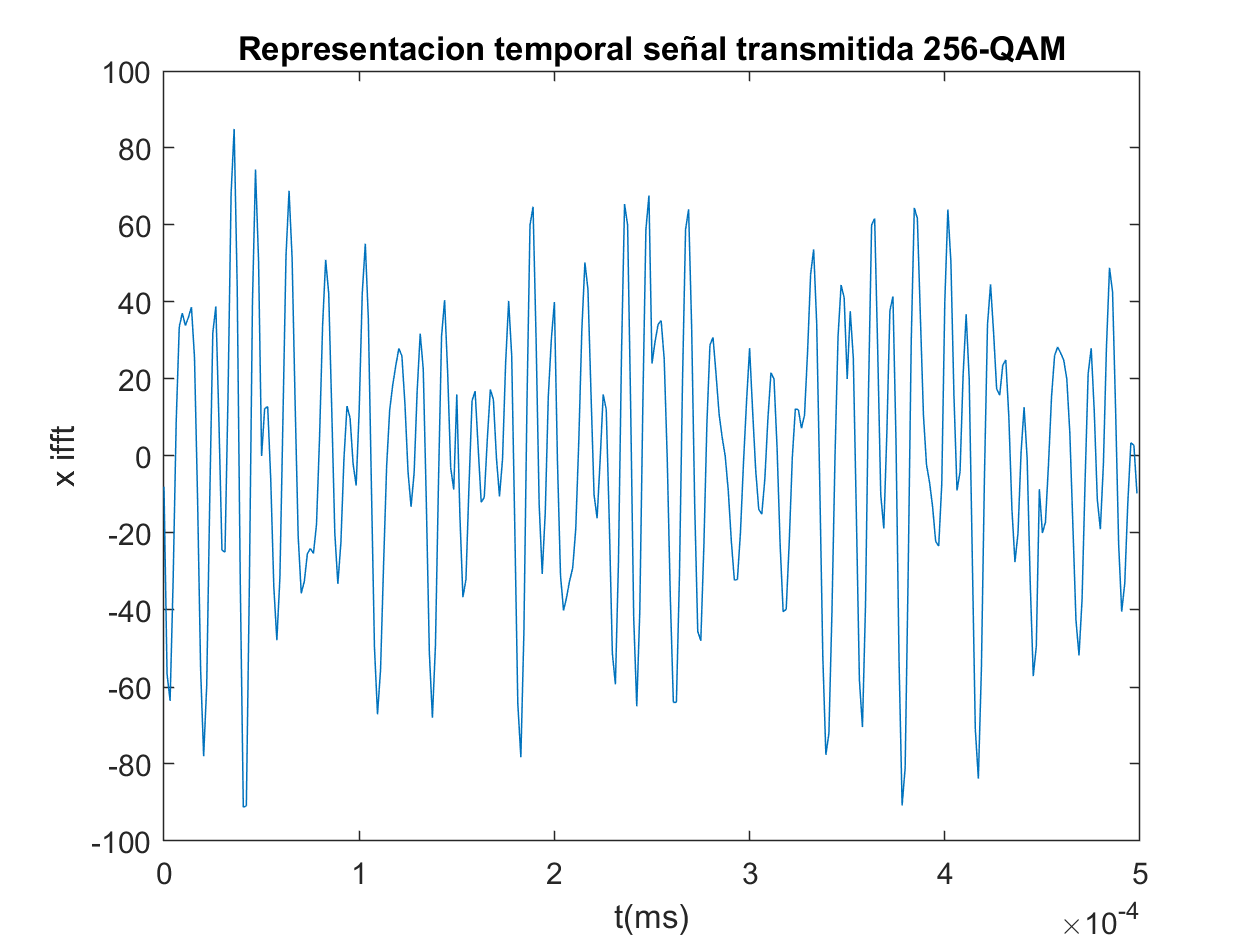

figure;
plot(t,x_256(1:10*NFFT))
xlabel('t(ms)');
ylabel('x ifft');
title('Representacion temporal señal transmitida 256-QAM');

A continuación se demodula la señal recibida. Puesto que se ha asumido un canal ideal sin ruido ni distorsión, esta es igual a la señal transmitida.

% Demodulación
y_16 = reshape(x_16,  [NFFT, Nofdm]);
y_64= reshape(x_64,  [NFFT, Nofdm]);
y_256 = reshape(x_256,  [NFFT, Nofdm]);

% Implementación de la FFT para demodular la señal OFDM.
% De nuevo la función fft de Matlab no modifica la amplitud a partir del
% número de puntos de NFFT, por lo que se hace manualmente para que
% coincida con la fórmula teórica.
Y_16 = fft(y_16,NFFT)/NFFT;
Y_64 = fft(y_64,NFFT)/NFFT;
Y_256 = fft(y_256,NFFT)/NFFT;

%Demodulación DQPSK
demod_16=reshape(Y_16(3:6,:), 1, []);
rxbits_16= qamdemod(demod_16,m_ary(1), 'OutputType', 'Bit');
rxbits_16 = reshape(rxbits_16,  1, []);

demod_64=reshape(Y_64(3:6,:), 1, []);
rxbits_64= qamdemod(demod_64,m_ary(2), 'OutputType', 'Bit');
rxbits_64 = reshape(rxbits_64,  1, []);

demod_256=reshape(Y_256(3:6,:), 1, []);
rxbits_256= qamdemod(demod_256,m_ary(3), 'OutputType', 'Bit');
rxbits_256 = reshape(rxbits_256,  1, []);

Se comprueba que el enlace funciona correctamente comparando los bits transmitidos y los recibidos. Para ello se calcula la BER, la cual debe ser cero ya que se ha asumido un canal ideal, es decir, sin ruido ni distorsión.

%Comprobar que la cadena mod-demod funciona. BER=0. TXBITS=RXBITS
BER_16= sum(abs(txbits_16-rxbits_16))/length(txbits_16); % Cálculo de BER
disp(['BER 16-QAM: '  num2str(BER_16)]);

BER 16-QAM: 0


BER_64= sum(abs(txbits_64-rxbits_64))/length(txbits_64);
disp(['BER 64-QAM: '  num2str(BER_64)]);

BER 64-QAM: 0


BER_256= sum(abs(txbits_256-rxbits_256))/length(txbits_256);
disp(['BER 256-QAM: '  num2str(BER_256)]);

BER 256-QAM: 0


Efectivamente, la BER para los tres formato de modulación es nula, por lo que se demuestra que el enlace funciona a la perfección.

### Implementacion de la FFT alternativa

Se implementa una función propia para calcular la FFT y se comprueba que esta funcione correctamente. La fórmula a utilizar es la siguiente:


$$$Y\left(k\right)=\frac{1}{NFFT}\sum_{n=1}^{NFFT}y(n)\cdot e^{\frac{-j2\pi} {NFFT} (k -1)( n-1)}$$$


%metodo FFT alternativo
Y_16_alt=fft_alt(y_16,NFFT, Nofdm, 0);
Y_64_alt=fft_alt(y_64,NFFT, Nofdm, 0);
Y_256_alt=fft_alt(y_256,NFFT, Nofdm, 0);

% Demostracion inexistencia de errores con implementacion FFT alternativa
error_16= abs(sum(demod_16-Y_16_alt));
disp(['Error entre FFTs para 16QAM: '  num2str(error_16)]);

Error entre FFTs para 16QAM: 7.5965e-14



error_64= abs(sum(demod_64-Y_64_alt));
disp(['Error entre FFTs para 64QAM: '  num2str(error_64)]);

Error entre FFTs para 64QAM: 1.7925e-13



error_256= abs(sum(demod_256-Y_256_alt));
disp(['Error entre FFTs para 256QAM: '  num2str(error_256)]);

Error entre FFTs para 256QAM: 5.4504e-13


La diferencia entre la señal obtenida mediante la implementación de la FFT de Matlab y la propia es menor de $6 \cdot 10^{-3}$ para todos los formatos de muestreo, por lo que el error es despreciable y podemos afirmar que son iguales. 

A continuación se comprueba que también demodula correctamente.


%demodulacion con alternativas
rxbits_16_alt= qamdemod(Y_16_alt,m_ary(1), 'OutputType', 'Bit');
rxbits_16_alt = reshape(rxbits_16_alt,  1, []);

rxbits_64_alt= qamdemod(Y_64_alt,m_ary(2), 'OutputType', 'Bit');
rxbits_64_alt = reshape(rxbits_64_alt,  1, []);

rxbits_256_alt= qamdemod(Y_256_alt,m_ary(3), 'OutputType', 'Bit');
rxbits_256_alt = reshape(rxbits_256_alt,  1, []);

%BER alt
BER_16_alt= sum(abs(txbits_16-rxbits_16_alt))/length(txbits_16); % Cálculo de BER
BER_64_alt= sum(abs(txbits_64-rxbits_64_alt))/length(txbits_64);
BER_256_alt= sum(abs(txbits_256-rxbits_256_alt))/length(txbits_256);
disp(['BER 16-QAM: '  num2str(BER_16)]);

BER 16-QAM: 0


disp(['BER 64-QAM: '  num2str(BER_64)]);

BER 64-QAM: 0


disp(['BER 256-QAM: '  num2str(BER_256)]);

BER 256-QAM: 0


De nuevo, la BER es nula para todos los formatos de modulación, por lo que el algoritmo es correcto.

## Degradacion por error en frecuencia

En este apartado se simulará la degradación que sufre la transmisión por un error de frecuencia, el cual es causadopor el efecto Doppler debido al movimiento del terminal. Su efecto es mayor cuanto mayor sea el nivel de modulación y más baja sea la separación entre portadoras.

A continuación se estudia la BER obtenida para errores en frecuencia de 0 a 0.2. Para la simulación se introduciro este error en el módulo de demodulación. Como se puede apreciar en la siguiente fórmula, se suma al parámetro k ($\frac{f_{c,i}}{f_{o} }$) el error (en nuestro caso el parámetro error_delta_f).


$$$Y\left(k\right)=\frac{1}{NFFT}\sum_{n=1}^{NFFT}y(n)\cdot e^{\frac{-j2\pi} {NFFT} (k+ \frac{\Delta f}{f0} -1)( n-1)}$$$


% Vector de error de frecuencia (f0)
% De 0 a 0.2 repartido en 200 muestras.
error_delta_f=0:0.2/199:0.2;

%inicializar BERs
BER_16_delta=zeros(1, length(error_delta_f));
BER_64_delta=zeros(1, length(error_delta_f));
BER_256_delta=zeros(1, length(error_delta_f));

%bucle para ir rellenando la BER por cada valor del error en f relativo
for k=1:length(error_delta_f)
    [BER_16_delta(k)] =  BER_delta_f(txbits_16, y_16, NFFT, Nofdm, error_delta_f(k),m_ary(1));
    [BER_64_delta(k)] =  BER_delta_f(txbits_64, y_64, NFFT, Nofdm, error_delta_f(k),m_ary(2));
    [BER_256_delta(k)] =  BER_delta_f(txbits_256, y_256, NFFT, Nofdm, error_delta_f(k), m_ary(3));
end

En la siguiente figura se representan las curvas de BER en función del error relativo en frecuencia para los trestipos de modulación n-QAM.

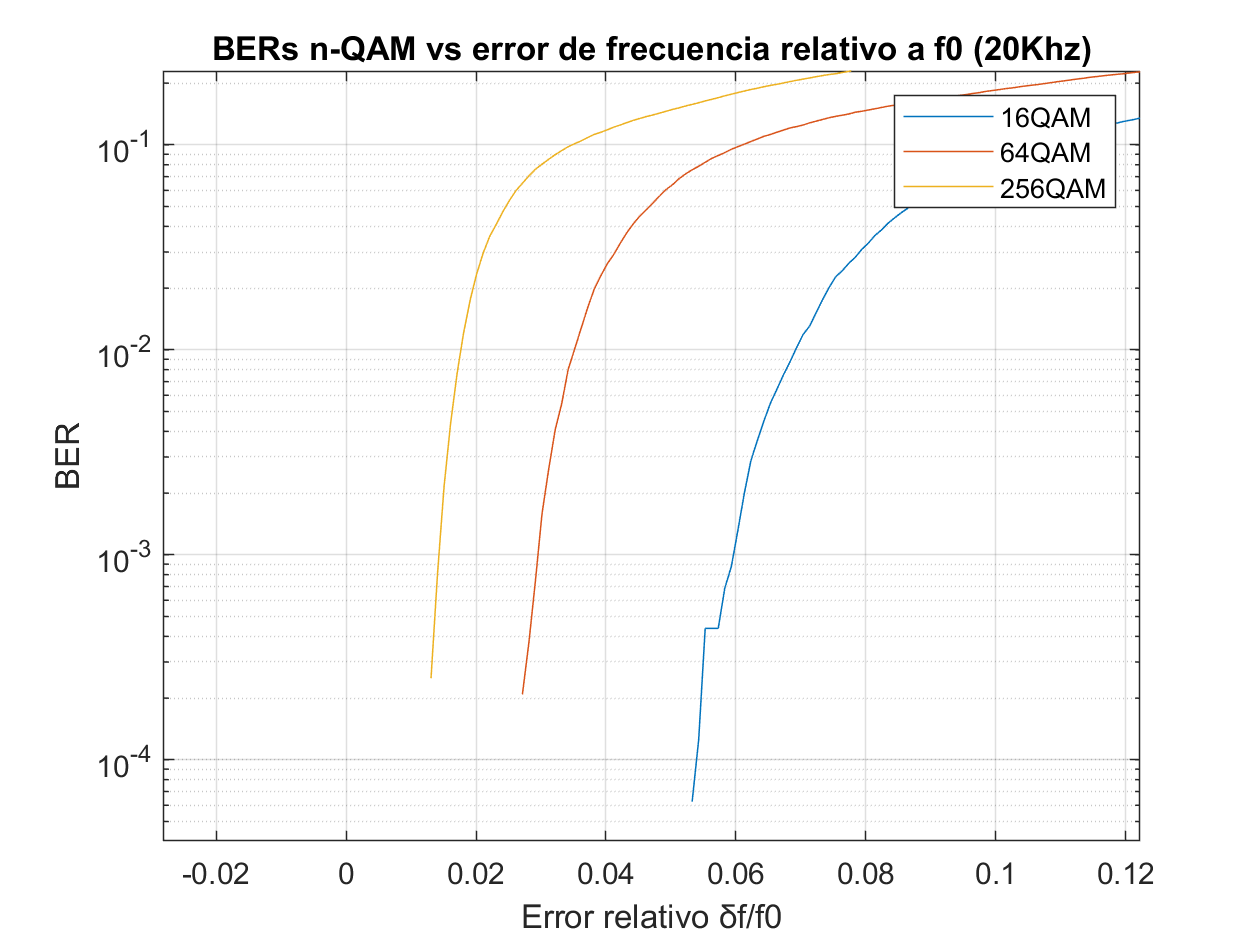

%Representacion BERs

figure
semilogy(error_delta_f, BER_16_delta);
hold on;
semilogy(error_delta_f, BER_64_delta);
hold on;
semilogy(error_delta_f, BER_256_delta);
xlabel('Error relativo δf/f0');
ylabel('BER');
title('BERs n-QAM vs error de frecuencia relativo a f0 (20Khz)');
legend ('16QAM', '64QAM', '256QAM');
grid on;

 Como se puede observar, la BER crece exponencialmente con la frecuencia para errores relativos pequeños y luego se estanca sobre 0.2. Tal y como se explicó en la introducción del apartado, el efecto es mayor cuanto mayor es el número de niveles de modulación. En particular, para $\frac{\Delta f}{f_o} = 0.06$, los valores de BER son los siguientes:

- **16-QAM : **0.001

- **64-QAM : **0.1

- **256-QAM: **0.17

Por otro lado, se puede observar  cómo la BER en 16QAM es prácticamente despreciable hasta un error relativo de aproximadamente 0.05, mientras que para 64QAM la BER es del orden de $ $10^{-4}$$ con un error relativo de 0.03 aproximadamente. Sin embargo, para 256QAM, la BER ya es del orden de$ $10^{-4}$$  con un error relativo de 0.01. Se concluye que, a mayor número de niveles, se consigue la misma BER con un error relativo menor, por lo que el sistema es más sensible ante una posible degradación en frecuencias en el caso de 256QAM que con las otras modulaciones.

## Conclusión

En esta práctica se han estudiado los efectos del error de en frecuencia causados por el efecto Doppler debido al movimiento de los terminales móviles en la correcta transmisión de señales OFDM. Se ha realizado una simulación de la BER para distintos valores de error $(\frac{\Delta f}{f_o} )$ y se ha representado en una gráfica. Se ha verificado que cuanto mayor es el error en frecuencia, mayor es el error en la transmisión. Además, a mayor número de niveles, con el mismo error relativo, mayor es la BER, ya que los puntos se encuentran más juntos en la constelación. 

Finalmente, se ha demostrado que la correcta sincronización en frecuencia es clave para las comunicaciones móviles.